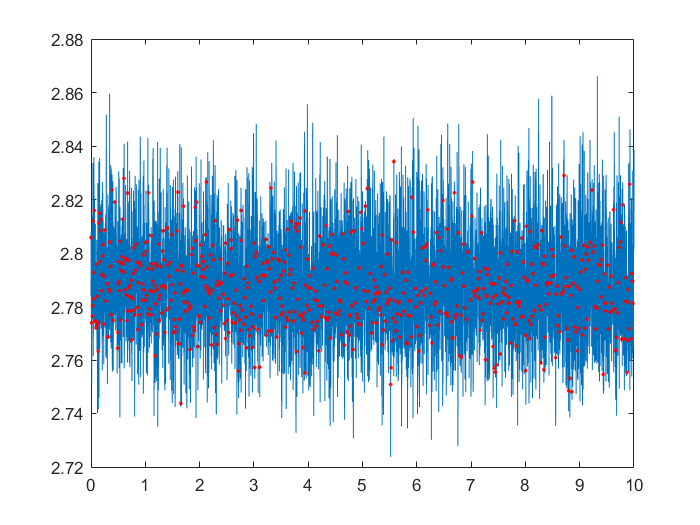

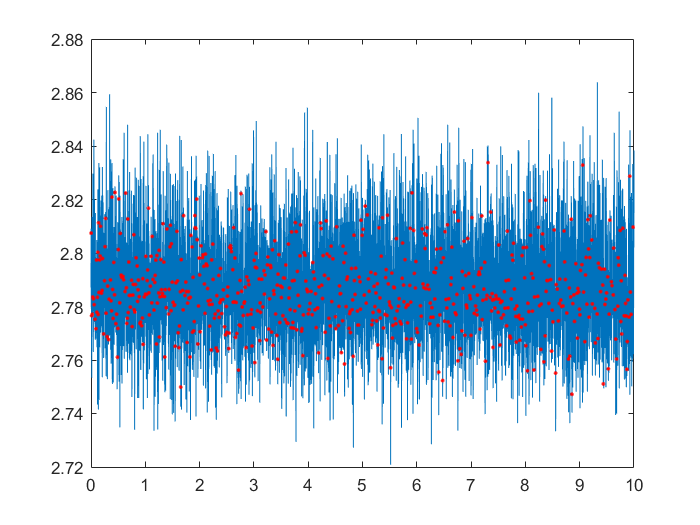

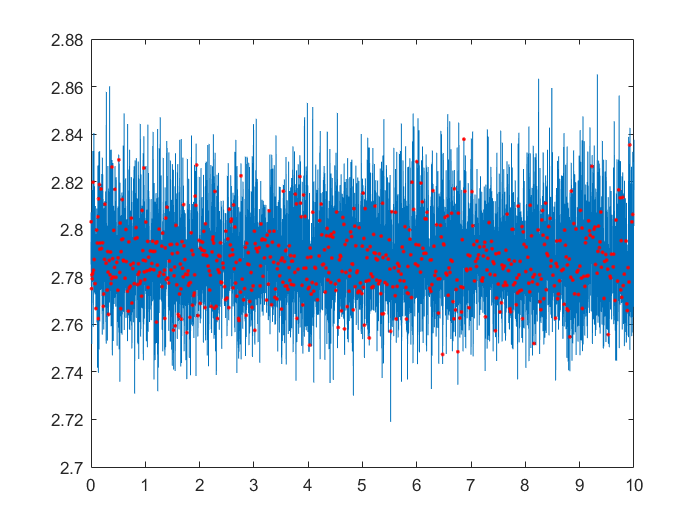

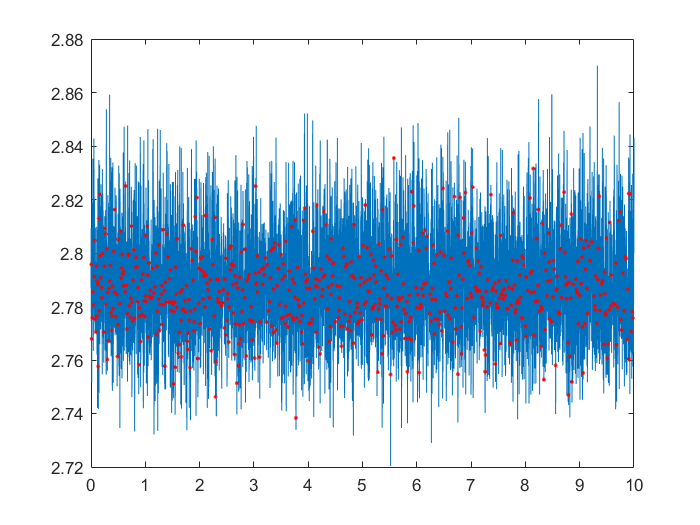

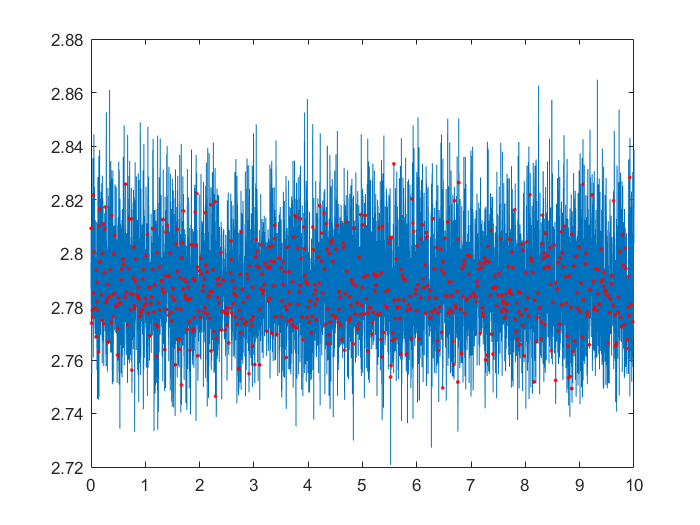

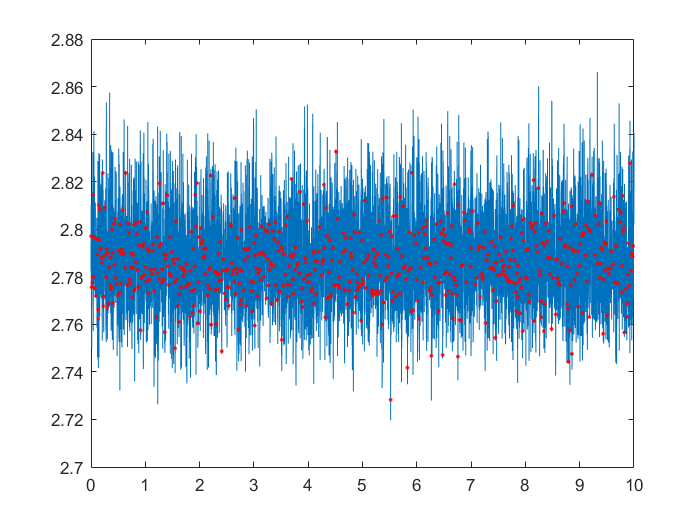

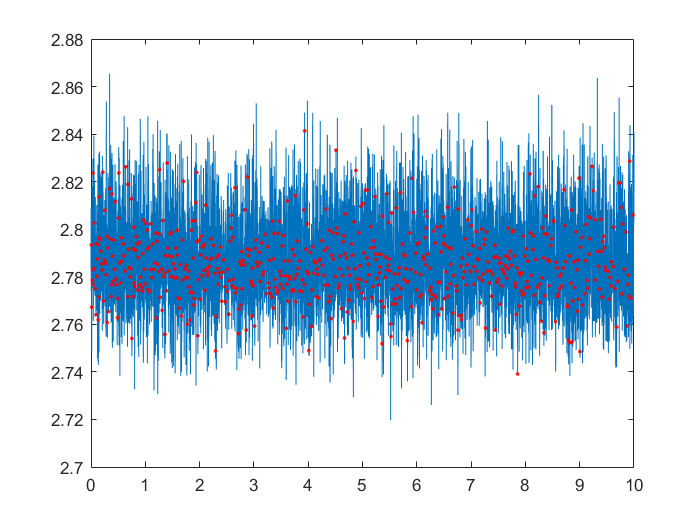

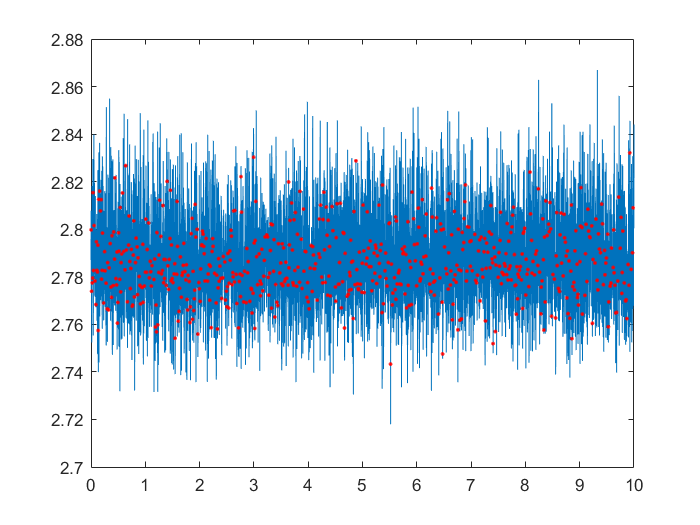

%Assuming a spike latency of 5 ms from a detected deflection.

fs = 10000;
for i = 1
    start = blwgn(i).OFF_dur * fs;
    stop = (blwgn(i).ON_dur + blwgn(i).OFF_dur)*fs;
    trial_length = blwgn(i).ON_dur;
    t = (0:1/fs: blwgn(i).ON_dur);
    
    stim = blwgn(i).antennal_movement(:,start:stop);
    raster = blwgn(i).raster(:,start:stop);
    
    latency = 0.005*fs;
    trials = blwgn(i).complete_trials;
    
    stim_level = NaN(trials,length(stim));
    stim_locs = NaN(trials, length(stim));
    for j=1:trials
        
        locs = find(raster(j,:));
        
        for k=1:numel(locs)
            if (locs(k)-latency)>=1
                stim_level(j,k)  = stim(j,locs(k)-latency);
                stim_locs(j,k) = (locs(k)-latency)/fs;
            end
        end
        figure;
        plot(t,stim(j,:)); hold on;
        plot(stim_locs(j,:),stim_level(j,:), 'r.'); 
    end
    
    
end